#### **4D Plot with Color Based on Another Matrix**

In this project, I extended the concept of a 3D surface plot by incorporating a fourth dimension through color mapping. This approach allowed me to visualize an additional layer of information on the surface, providing a richer and more insightful representation of the data.

To begin, I generated the x and y values using `meshgrid` and computed the z-values with the same function. To add the fourth dimension, I created a matrix C, which defined the color of the surface. This matrix was based on the expression, introducing variations in color based on the combined influence of x and y values.

Using MATLAB’s `surf` function, I plotted the surface, assigning the color of each point to the corresponding value in C. The result was a vibrant visualization where the colors represented the fourth dimension. I chose the 'cool' colormap for its gradient of warm colors, which intuitively conveyed variations in intensity. Adding a colorbar further clarified the relationship between color and the values in C.

This enhanced plot revealed both the shape of the surface and the additional dimension encoded in the colors, making it a powerful tool for multidimensional analysis

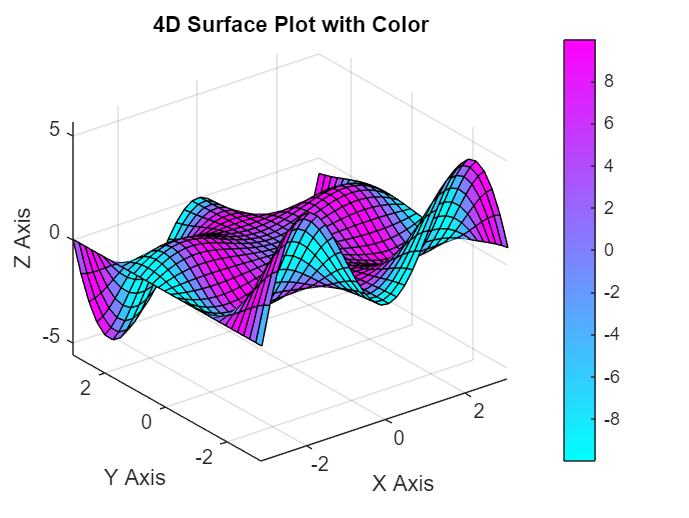

% Creating a 4D Surface Plot
% I want to add a second matrix to color the surface based on additional information.

% Generate the color data
C = 10 * sin(0.5 * (x.^2 + y.^2));

% Plot the surface with color defined by C
figure;
surf(x, y, z, C); % Use C to define the color of the surface
xlabel('X Axis');
ylabel('Y Axis');
zlabel('Z Axis');
grid on;
colormap('cool');
colorbar;
title('4D Surface Plot with Color');